# Processing Data Samples from MRI

## Data Collection

Library is already loaded.

Functions in library libModuleConnector64:

data_reader_at_end                    nva_read_message_presence_single      
data_reader_close                     nva_read_x4_spi                       
data_reader_create                    nva_reset                             
data_reader_destroy                   nva_run_timing_measurement            
data_reader_get_data_types            nva_send_command                      
data_reader_get_duration              nva_send_command_single               
data_reader_get_filter                nva_set_X2_float                      
data_reader_get_max_record_size       nva_set_X2_int                        
data_reader_get_session_id            nva_set_X2_register                   
data_reader_get_size                  nva_set_basename_for_data_type        
data_reader_get_start_epoch           nva_set_debug_level                   
data_reader_is_open                   nva_set_detection_zone                
data

Packets available: 0
Packets available: 0
Packets available: 1
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Packets available: 0
Read 900 frames. A total of 900 were sent from chip. Frames dropped: 0
Estimated FPS: 89.9162, should be: 90
Closing radar


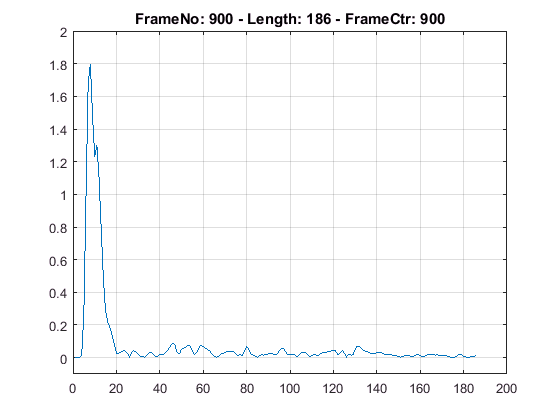

Fs = 90.0;
Duration = 10.0; % Seconds
addpath(experiments);
raw_chest_sample = acquire_radar_data(Fs, Duration);

Drawing the Raw Data

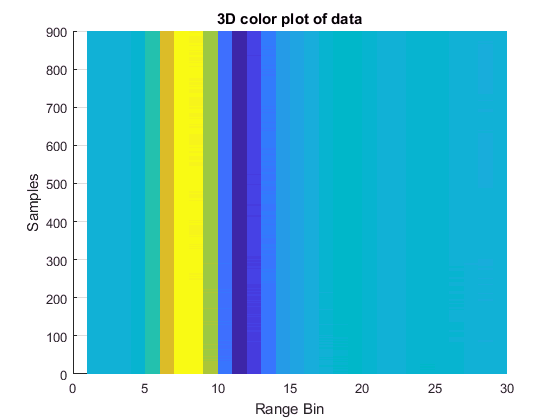

Fs = 60.0;
Duration = 30.0; % Seconds
%load("data/raw_chest_sample_jason.mat");

figure(1);
raw_chest_sample_real = real(raw_chest_sample);
surf(raw_chest_sample_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
view(2);
xlabel('Range Bin')
ylabel('Samples')

figure(2);

Remoing the offset of the sent information

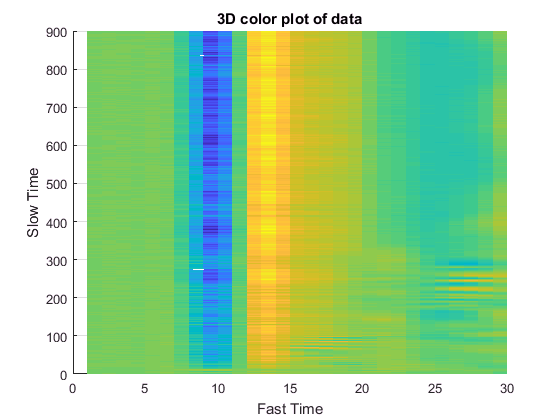

[slowTime, fastTime] = size(raw_chest_sample);
chest_sample = zeros(slowTime, fastTime);
zero_sample = raw_chest_sample(450,:);
for i=1:slowTime
    chest_sample(i,:) = raw_chest_sample(i,:) - zero_sample;
end
chest_sample_real = real(chest_sample);
surf(chest_sample_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
xlabel('Fast Time')
ylabel('Slow Time')
view(2);


clear i zero_sample;

Getting the velocity from the information

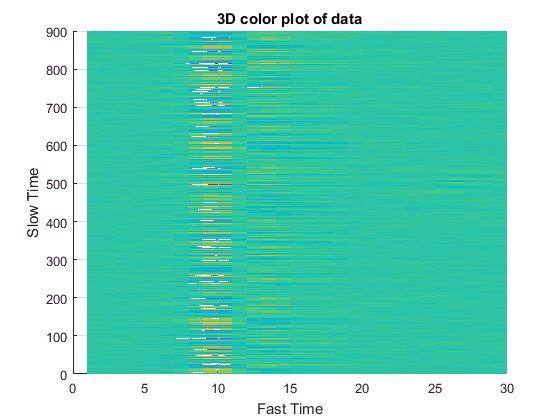

chest_sample_vel = zeros(slowTime , fastTime);
chest_sample_vel(1,:) = chest_sample(1,:);
for i=2:slowTime
    chest_sample_vel(i,:) = chest_sample(i,:) - chest_sample(i-1,:);
end
chest_sample_vel_real = real(chest_sample_vel);
surf(chest_sample_vel_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
xlabel('Fast Time')
ylabel('Slow Time')
view(2);

% Calculating Respiratory Rate from the 3D plot by finding the lowest point
% at a certain time and find the positions for that lowest time
lowest_time = zeros(slowTime, 0);
lowest_point = zeros(slowTime, 0);
for i = 1:slowTime
   [lowest_point(i), lowest_time(i)] = min(chest_sample_real(i,1:30));
end
plot(real(lowest_point));

Moving Average

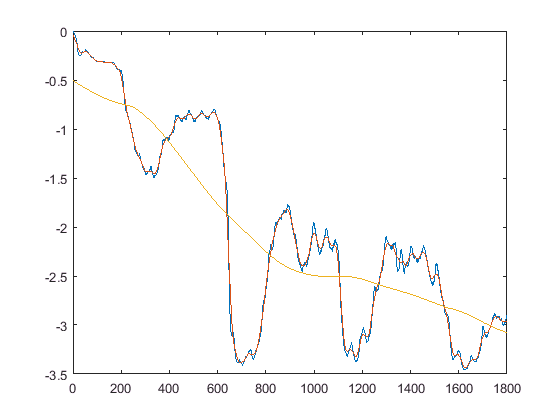

hold on;
lowest_point_moving = movmean(lowest_point, 29);
lowest_point_moving_2 = movmean(lowest_point,99);
lowest_point_moving_3 = movmean(lowest_point_moving_2,299);
lowest_point_moving_4 = movmean(lowest_point_moving_3,499);
plot(real(lowest_point_moving));
plot(real(lowest_point_moving_4));
hold off;

Taking the difference between the moving average and the sample

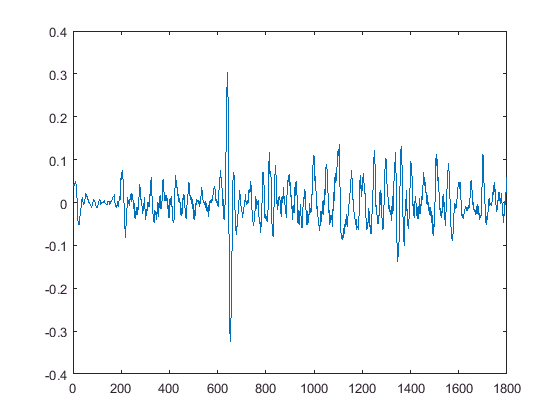

hr_diff = lowest_point - lowest_point_moving;
plot(real(hr_diff));

L = length(hr_diff);

Calculating the overall spectrum

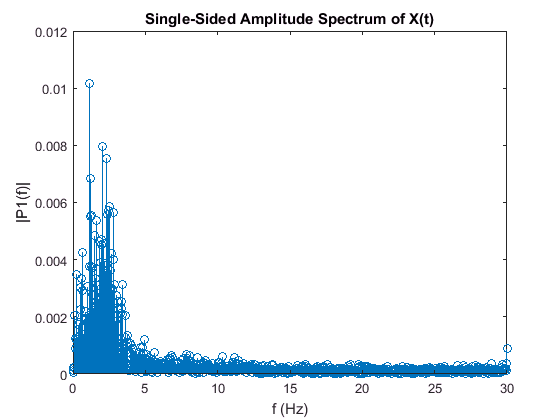

hrfft = fft(hr_diff);
hrfft = abs(hrfft/L);
hrfft = hrfft(1:L/2+1);
f = Fs*(0:(L/2))/L;
stem(f,hrfft) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


[~, hr_index] = max(hrfft);
hr = f(hr_index) * 60;

clear i L lowest_point_moving_2 lowest_point_moving_3 hr_index hr_max;

Model of the Noise

Shifting the windows to get a rate over time

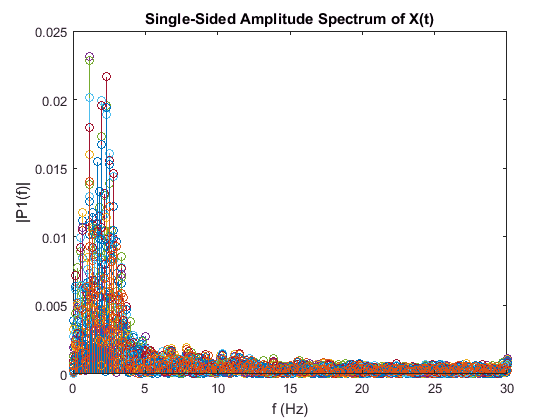

% Need to loop
window_size = 360;
shift_sample_rate = 4;
sample_count = (slowTime - window_size)/window_size * shift_sample_rate;

window = zeros(window_size);
hr_time = zeros(sample_count);

f = Fs*(0:(window_size/2))/window_size;

hold on;
for i=1:sample_count-1
    start = i*window_size/shift_sample_rate;
    finish = i*window_size/shift_sample_rate + window_size;
    window = hr_diff(start:finish);
    
    % Get the FFT
    hrffts = fft(window);
    hrffts = abs(hrffts/window_size);
    hrffts = hrffts(1:window_size/2+1);
    
    stem(f, hrffts);
    hr_time(i) = mean(hrffts.*f);
    % Use the 
    
end
hold off;

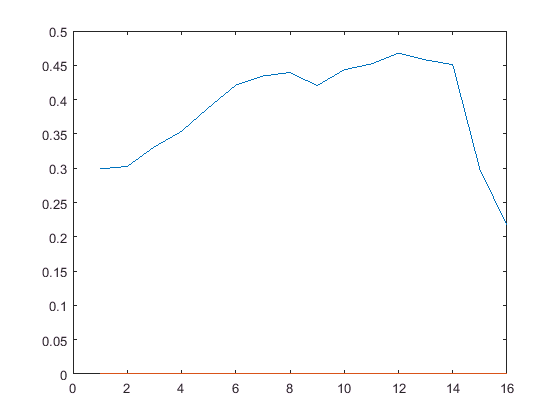

hr_time = hr_time * 60;
hr_time = movmean(hr_time, 3);
plot(hr_time);

Using a Filter

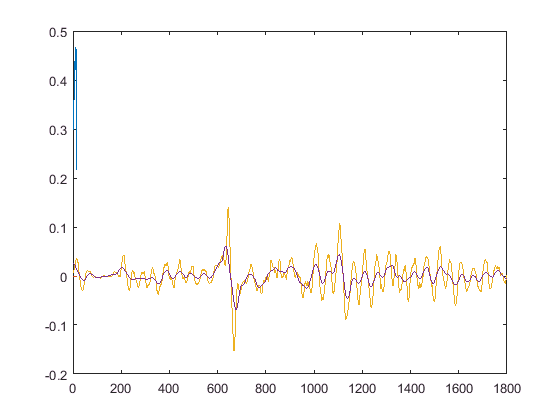

% Using filter
% hrFilter = designfilt('bandpassfir', 'StopbandFrequency1', 0.5, 'PassbandFrequency1', 0.6, 'PassbandFrequency2', 2.0, 'StopbandFrequency2', 2.5, 'StopbandAttenuation1', 60, 'PassbandRipple', 1, 'StopbandAttenuation2', 60, 'SampleRate', 60);
load('hrFilter.mat');
hrFilted = filter(hrFilter, hr_diff);
hold on;
plot(real(hrFilted));
hrFiltedMov = movmean(hrFilted, 39);
plot(real(hrFiltedMov));
hold off;

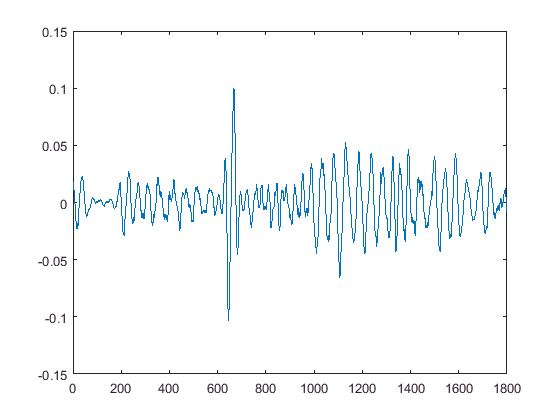

plot(real(hrFiltedMov - hrFilted));

## Spline Curve Modelling

% Using a Bivariate Tensor Product Spline
chest_sample_interpolated = cubic_spline_3d(chest_sample_real);

Error using chckxywp (line 76)
There should be at least 2 data sites.

Error in spapi>spapi1 (line 154)
   [x,y,sizeval] = chckxywp(x,y);

Error in spapi (

surf(chest_sample_interpolated(1:end, 1:end), 'EdgeColor', 'None');

